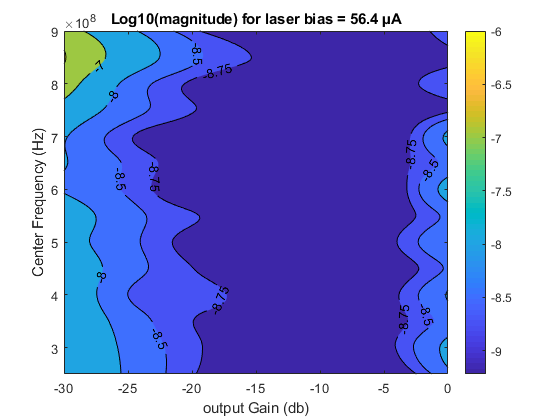

%Laser bias (in micro ampere)%
Laser_bias = 56.4; 

minGain = -30; %minimum transmited power gain (in db)
maxGain =  0; %maximum transmited power gain (in db)
padGain = 5;   %measure pad for gains
numMeasurmentsGain = (abs(minGain) - abs(maxGain))/padGain;

minCarrierFrequency =  2.5e8; %minimum center frequency supported by adalm pluto (in hz)
maxCarrierFrequency =  9e8; %maximum centr frequency supported by the laser (in hz)
padCarrierFrequency =  50000e3; %pad of 10 khZ
numMeasurementsFreq = (maxCarrierFrequency-minCarrierFrequency)/padCarrierFrequency;


x = minGain : padGain : maxGain;
y = minCarrierFrequency : padCarrierFrequency : maxCarrierFrequency;

%-1.0000 + 0.0000i
data_EVR_bpsk = [0.183865572547479,0.155729387350812,0.134043640872998,0.129539755464000,0.125679302644544,0.123311201208906,0.152342864204047;
    0.197092766107109,0.153478956341195,0.135307716535988,0.127055851916528,0.126588426438010,0.129691764893106,0.165636807750474;
    0.190918219070994,0.149334460568946,0.133492113127030,0.130870969704690,0.125077064633296,0.128398822992383,0.146835018176185;
    0.191881333692509,0.141124009124451,0.136371951716711,0.131192768390026,0.129249829005937,0.129250048398882,0.160299680477311;
    0.183786537151299,0.147414079192066,0.133553270002887,0.129190125115302,0.127147146814299,0.126771250890769,0.143032268826766;
    0.170186663689446,0.144847525569903,0.130467416577182,0.131961749548294,0.124641169573667,0.129797924636765,0.157602916855361;
    0.176054793519154,0.146009039483279,0.134146250105418,0.129905618621901,0.127848181053710,0.127172984474091,0.144602955195543;
    0.156726604734257,0.139420886890536,0.126251839795012,0.130616221351244,0.122597425591767,0.123131672105617,0.170325960880703;
    0.160005904870361,0.139636757583488,0.128985549487905,0.129405076083387,0.125029721547355,0.128266011583152,0.144785225708363;
    0.160553616209615,0.134451956095569,0.127258864704055,0.124190471517648,0.128929413456957,0.123457309888766,0.163793238481979;
    0.183615790995773,0.147311361607315,0.133827404626815,0.129806042856505,0.127186835149414,0.126320879540816,0.132126378166288;
    0.224117078032165,0.152321177675674,0.131939682256251,0.127403714577607,0.130559088162001,0.129446001551789,0.139396688497125;
    0.254329273741531,0.179214584767808,0.144542179382772,0.132923260038963,0.131790409261884,0.128466053630514,0.130905679834598;
    0.221390284382151,0.164001442696094,0.135324375092763,0.125965497335049,0.122211989988260,0.121039132058189,0.141940079788461];

data_ber_bpsk = [0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0];



figure (1)
z1 = 10*log10(data_EVR_bpsk);
[Xq,Yq] = ndgrid(minGain:(padGain/10):maxGain,...
    minCarrierFrequency:(padCarrierFrequency/10):maxCarrierFrequency);
% Vq = F(Xq,Yq);
Vq = interp2(x,y,z1,Xq,Yq,'cubic');
contourf(Xq,Yq,Vq,[-11 -10  -8 -8.5 -8.75 -7 -6 -5 0 ],'ShowText','on');
colorbar 
title('Log10(magnitude) for laser bias = 56.4 µA');
xlabel('output Gain (db)');
ylabel('Center Frequency (Hz)');

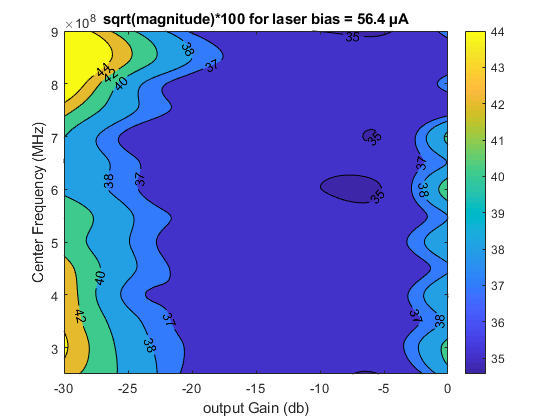



figure (2)
z3 = sqrt(data_EVR_bpsk)*100;
[Xq,Yq] = ndgrid(minGain:(padGain/10):maxGain,...
    minCarrierFrequency:(padCarrierFrequency/10):maxCarrierFrequency);
% Vq = F(Xq,Yq);
Vq = interp2(x,y,z3,Xq,Yq,'cubic');
contourf(Xq,Yq,Vq,[44 42 40 38 37 35 34 32 30],'ShowText','on');
colorbar 
title('sqrt(magnitude)*100 for laser bias = 56.4 µA');
xlabel('output Gain (db)');
ylabel('Center Frequency (MHz)');